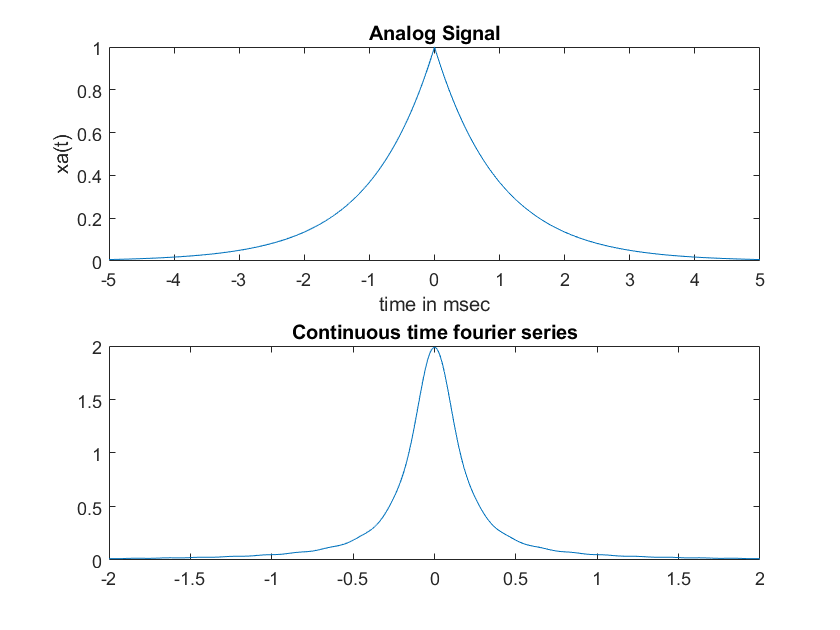

%Analog signal
fs=2000; % signal frequency
dt=0.00005; 
t=-0.005:dt:0.005; % time -5ms to 5ms
xa=exp(-1000*abs(t)); %signal
%CTFT
Wmax=2*pi*fs; %angular frequency of signal
K=500; %number of points
k=0:1:K; %point array
w=k*Wmax/K; %angular frequency array
Xa=xa*exp(-1j*t'*w)*dt; %CTFT of signal
Xa=real(Xa); %real part of signal
w=[(-fliplr(w)),w(2:K+1)]; % make symmetry array of frequncy in khz
Xa=[fliplr(Xa),Xa(2:K+1)]; % make smmetry array of real part of CTFT
subplot(2,1,1)
plot(t*1000,xa)
title('Analog Signal')
xlabel('time in msec')
ylabel('xa(t)')
subplot(2,1,2)
plot(w/(2*pi*1000),Xa*1000)
title('Continuous time fourier series')